**Real-time Digital Signal Processing Laboratory**

**Lab 4**

**Soroush Mesforush Mashhad - 810198472**

clc
clear all

Part 1

Here we shall create the given IIR elliptic filter then we shall go on to plot its frequency response.

load('FilterOutImp.txt')

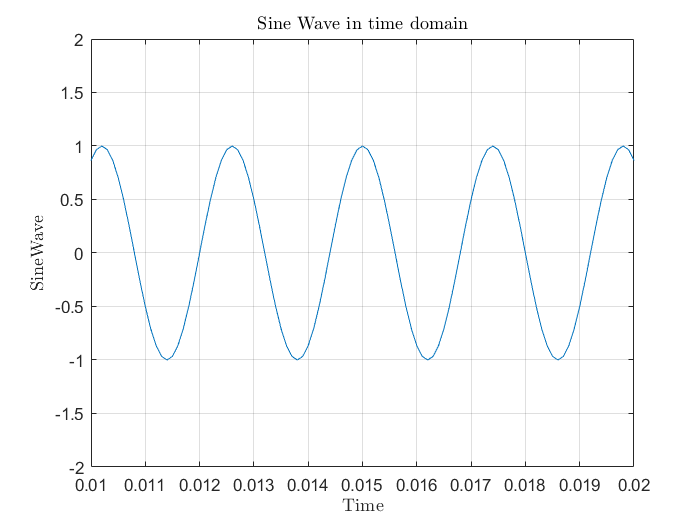

fs = 10000;
t = 0:1/fs:1-1/fs;
plot(t, FilterOutImp);
grid on;
xlim([0.01 0.02 ])
ylim([-2 2])
xlabel('Time','Interpreter','latex')
ylabel('SineWave','Interpreter','latex')
title('Sine Wave in time domain','Interpreter','latex');

Now we shall plot the fourier transform of the sine wave

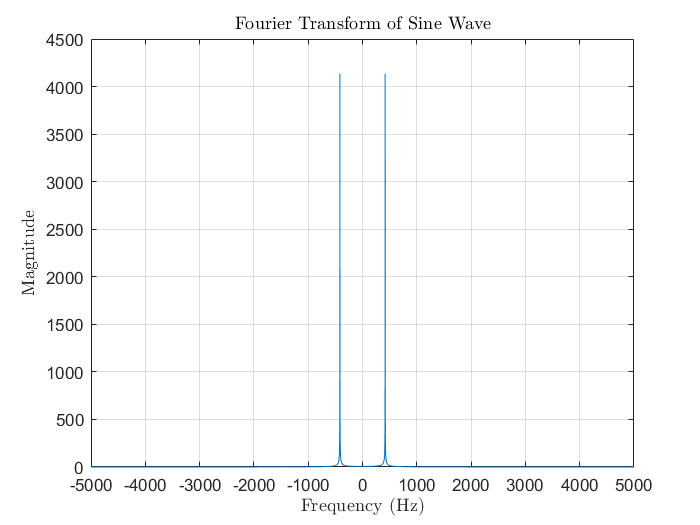

SineFFt = fftshift(fft(FilterOutImp));
f = fs/2*linspace(-1,1,fs);
figure;
plot(f, abs(SineFFt));
grid on;
title('Fourier Transform of Sine Wave','Interpreter','latex')
xlabel('Frequency (Hz)','Interpreter','latex');
ylabel('Magnitude','Interpreter','latex');